This is a program that will create a plot of the 2D potential function landscape for a system of three symmetrically coupled HKB oscillators, both for identical oscillators (i.e., all oscillators share the same natural frequency) and for nonidentical oscillators (i.e., the three oscillators have different natural frequency parameters.

In general, the potential function for a system of three coupled HKB oscillators is given by 


$$\begin{array}{l}
V\left(\phi_1 ,\phi_2 \right)=-\delta \omega_1 \phi_1 -\delta \omega_2 \phi_2 -A_{01} \cos \phi_1 -A_{02} \cos \phi_2 -A_{12} \cos \left(\phi_1 -\phi_2 \right)\\
-B_{01} \mathrm{cos2}\phi_1 -B_{02} \mathrm{cos2}\phi_2 -B_{12} \mathrm{cos2}\left(\phi_1 -\phi_2 \right)
\end{array}$$


We will now produce a plot of this function for a set of points $\phi_1$ and $\phi_2$ over a prespecified range.

First, define the range for $\phi_1$ and $\phi_2$.

x = -2*pi:0.25:2*pi;

[phi_1,phi_2] = meshgrid(x);

Now, set the coupling strengths and frequency difference parameters.

A_01 = 1;
A_02 = 1;
A_12 = 1;

B_01 = 4;
B_02 = 4;
B_12 = 4;


delta_omega_1 = 1;
delta_omega_2 = 1;

Next, define the potential function.

V = -delta_omega_1*phi_1 - delta_omega_2*phi_2 - A_01*cos(phi_1) ...
    - A_02*cos(phi_2) - A_12*cos(phi_1 - phi_2) - B_01*cos(2*phi_1) ...
    - B_02*cos(2*phi_2) - B_12*cos(2*(phi_1 - phi_2));

Finally, create a surface plot of this potential function.

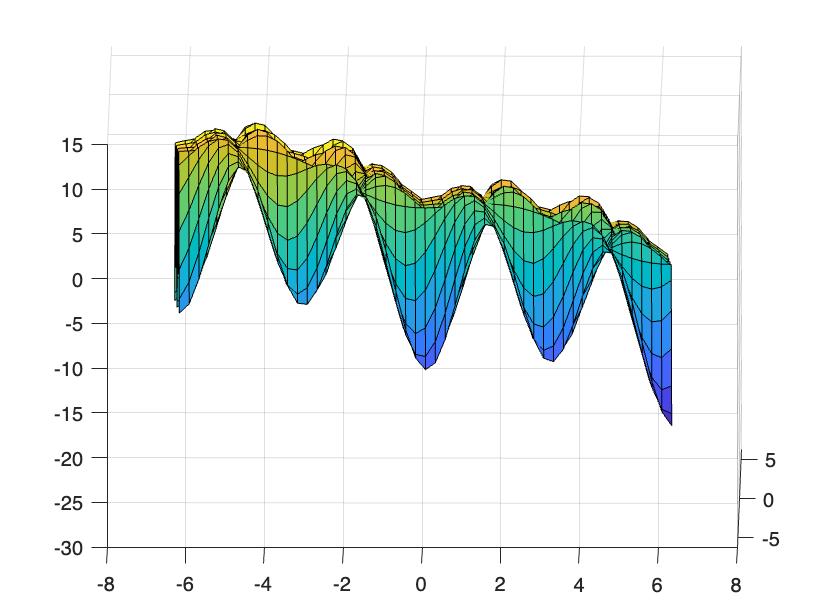

surf(phi_1, phi_2, V)

This will output the HKB potential function for a system of three coupled oscillators.  

We can fix the natural frequencies and the coupling strengths for two of the oscillators and observe how their coordination dynamics, as visualized by the potential landscape, vary as a function of the natural frequency and coupling parameters of the third oscillator.  **This reveals the phenomenon of third-party entrainment.**